Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Beam-beam disruption (Section 9.8)

Volker Ziemann, 211113, CC-BY-SA-4.0

In the example we simulate the collision of two bunches at the interaction point of the linear collider CLIC, operating at 1.5 TeV beam energy. The beam sizes are so small that the electromagnetic fields violently affect the counter-propagating bunch and change its beam sizes during the collision. Here we follox te beam size of longitudinal slices inside each bunch and carefully keep of which slices meet. We make the simplifying assumption that the beam-beam force is linear inside the bunch and change the angular divergence of each slice.

At the start of the simulation we define the parameters, such as the initial beam sizes in all three dimensions. These parameters will apply to both counter-propagating beams.

clear all; close all;
Relec=2.8179e-15;        % classical electron radius
Energy=1500e9; gamma=Energy/511e3;
Nbunch=3.72e9; sigz=44e-6;
epsx=2.286e-13; betax=7e-3;     % sigx=40 nm
epsy=1.471e-14; betay=68e-6;    % sigy=1 nm
sigx=sqrt(epsx*betax); sigy=sqrt(epsy*betay);

Now we split the bunch into 100 longitudinal slices and fill each slice with the appropriate number of particles. We also initialize the beam matrices `siga` and `sigb` for the slices with the design emittances and beta functions at the interaction point. Here we assume the beams to be colliding head-on, which implies that forthe centroids we have `Xa=Xb=0`.

Nslices=100;                           % over plus-minus 3 sigmaz
z=-3*sigz:6*sigz/(Nslices-1):3*sigz;   % position of slice
dz=z(2)-z(1);                          % length of longitudinal slice
Na=exp(-0.5*(z./sigz).^2); Na=Nbunch*Na/sum(Na); Nb=1*Na;  % particles in slice
siga=zeros(4,4,Nslices); sigb=siga;    % beam matrix of slice
Xa=zeros(4,1,Nslices); Xb=Xa;          % Centroid of slice
siga(1,1,1)=epsx*betax; siga(2,2,1)=epsx/betax;
siga(3,3,1)=epsy*betay; siga(4,4,1)=epsy/betay;

Since the beams have a latge angular divergence, the beam matrices siga and sigb at the start of the simulation are actually bigger and depend on the distance of a slice from the interaction point. We therefore back-propagate the beam matrices to their appropriate starting point in the fllowing code snippet.

for k=1:Nslices % initialize the sigma matrices in all slices
  R=eye(4); R(1,2)=-(k-1)*dz; R(3,4)=R(1,2);  % propagate backwards
  siga(:,:,k)=R*siga(:,:,1)*R';
  sigb(:,:,k)=siga(:,:,k);
end

Now we calculate the luminosity ${\cal L}_0$ in the zero-current limit with Equation 9.21.

ssig=[siga(1,1)+sigb(1,1),siga(1,3)+sigb(1,3); ...
    siga(1,3)+sigb(1,3),siga(3,3)+sigb(3,3)];
lumi_total0=sum(Na)*sum(Nb)/(2*pi*sqrt(det(ssig)))

lumi_total0 = 2.7525e+34

After initializing arrays to store the horizontal and vertical beam sizes of the slices for display, we loop over the the time t. In each time step, we then loop over the slices` j` and determine the corresponding slice` k` in the couter-propagating beam that this particular slice meets. Then we call `collide_slices()`, defined below, to update the beam matrix, the centroid and return the luminosity the these two colliding slices contribute. 

sax=zeros(1,Nslices); say=sax; sbx=sax; sby=sax;  % for display
lumi_total=0;
for t=0:2*Nslices-2    % loop over time steps
  for j=1:Nslices      % loop over the slices that meet at time t
    k=t+2-j;           % plus 2 because of indexing that starts at 1
    if ((k<1) || (k>Nslices)) continue; end  % abort if slices do not meet
    [sa,xa,sb,xb,lumi]=collide_slices(siga(:,:,j),Xa(:,:,j),Na(j), ...
       sigb(:,:,k),Xb(:,:,k),Nb(k),dz,gamma);
    siga(:,:,j)=sa; Xa(:,:,j)=xa;   % copy back updated values
    sigb(:,:,k)=sb; Xb(:,:,k)=xb;
    lumi_total=lumi_total+lumi;      % sum the luminosity per slice
  end

Once we have the updated beam matrices we extract the transverse beam sizes and copy them to the the arrays used for display. The arrays za and zb contain the longitudinal positions to which the slices have moved at this time step.

  for k=1:Nslices % copy to display-arrays in nm
    sax(k)=1e9*sqrt(siga(1,1,k)); say(k)=1e9*sqrt(siga(3,3,k));
    sbx(k)=1e9*sqrt(sigb(1,1,k)); sby(k)=1e9*sqrt(sigb(3,3,k)); 
  end
  za=1e6*dz*((1:Nslices)-t/2-1); zb=1e6*dz*(-Nslices+(1:Nslices)+t/2);

The first subplot shows the longitudinal distribution of the slices as they move into each other. Beam a is shown as a black line and beam b as a dash-dotted red line. Note that the time is displayed at the top right corner.

  subplot(3,1,1);
  plot(za,Na,'k',zb,flip(Nb),'r-.','LineWidth',2)
  xlim([-Nslices*dz*1e6,Nslices*dz*1e6]); ylabel('N/slice')
  text(180,8e7,['t = ',num2str(1e15*t*dz/(2*3e8),4),' fs'],'FontSize',10)

The next two subplots show the evolution of the transverse beam sizes of the slices during the collision. Note the violent disruption of expecially the vertical beam size, which is due to the strong electro-magnetic forces that cause one beam to focus the other. The focal length from the beam-beam deflection is shorter than the bunch length $\sigma_z$ in this case. 

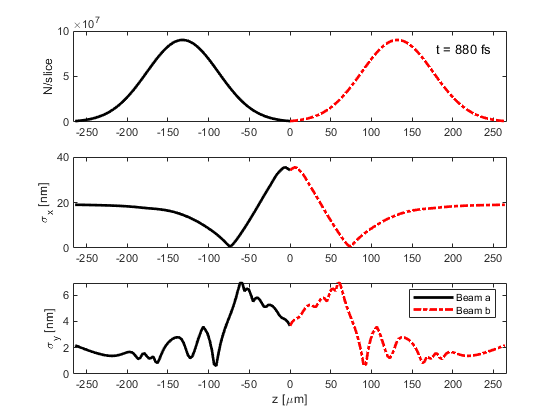

  subplot(3,1,2);
  plot(za,sax,'k',zb,flip(sbx),'r-.','LineWidth',2)
  xlim([-Nslices*dz*1e6,Nslices*dz*1e6]); ylabel('\sigma_x [nm]')
  subplot(3,1,3);
  plot(za,say,'k',zb,flip(sby),'r-.','LineWidth',2)
  xlim([-Nslices*dz*1e6,Nslices*dz*1e6]);
  ylabel('\sigma_y [nm]'); xlabel('z [\mum]')
  legend('Beam a','Beam b');
  pause(0.01)
end

Finally we compare the total luminosity with  disruption with the zero-current luminosity we calculated beefore and find that the luminosity is actually enhanced, which is a consequence of the beam focussing each other. The beam sizes actually get smaller during the collision.

enhancement_factor=lumi_total/lumi_total0

enhancement_factor = 1.5833

This is the simuation used for Figure 9.9 in Section 9.8 in the book. Now feel free to experiment.

## Appendix

The function `collide_slices()` receives the beam sizes, the centroids, and the number of particles in a slice, as well as the beam energy, specified by the reativistic factor gamma, as input and returns the updated values of these parameters and the contribution to the total luminosity. Inside the function first the inverse focal length, correpsonding the the electro-magnetic forces of one beam on the other  are calculated and passed to the function `CTM()`, which returns the transfer matrix that propagates the slice of beam` a`. Then we do the same thing for beam `b`. At the end we propagate the beam matrices of the slice by this *linearized* model of the beam-beam force. Along the way we calculate the contribution to the luminosity `lumi` from the collision of these two slices. 

function [siga2,Xa2,sigb2,Xb2,lumi]=collide_slices(siga,Xa,Na,sigb,Xb,Nb,dz,gamma)
Relec=2.8179e-15;        % classical electron radius
sx=sqrt(sigb(1,1)); sy=sqrt(sigb(3,3));
fxinv=2*Nb*Relec/(gamma*sx*(sx+sy));
fyinv=2*Nb*Relec/(gamma*sy*(sx+sy));
Ra=CTM(dz,fxinv,fyinv);        % Field from b to deflect a
sx=sqrt(siga(1,1)); sy=sqrt(siga(3,3));
fxinv=2*Na*Relec/(gamma*sx*(sx+sy));
fyinv=2*Na*Relec/(gamma*sy*(sx+sy));
Rb=CTM(dz,fxinv,fyinv);         % Field from a to deflect b
ssig=[siga(1,1)+sigb(1,1),siga(1,3)+sigb(1,3); ...
    siga(1,3)+sigb(1,3),siga(3,3)+sigb(3,3)];
lumi=Na*Nb/(2*pi*sqrt(det(ssig)));
Xa2=Ra*Xa; siga2=Ra*siga*Ra';  % update beam a
Xb2=Rb*Xb; sigb2=Rb*sigb*Rb';  % and beam b
end

The function CTM() receives the length of a slices and the inverse focal lengths in the transverse planes and returns a $4\times 4$ transfer matrix R that is composed of thin lens focusing elements sandwiched between drift spaces having half the length of a slice. 

% CTM.m, collision transfer matrix
function R=CTM(dz,fxinv,fyinv)
D=eye(4); D(1,2)=0.5*dz; D(3,4)=0.5*dz;
Q=eye(4); Q(2,1)=-fxinv; Q(4,3)=-fyinv;
R=D*Q*D;
end